# Neural Networks

## 1. What are neural networks?

### The analogy of the neuron 

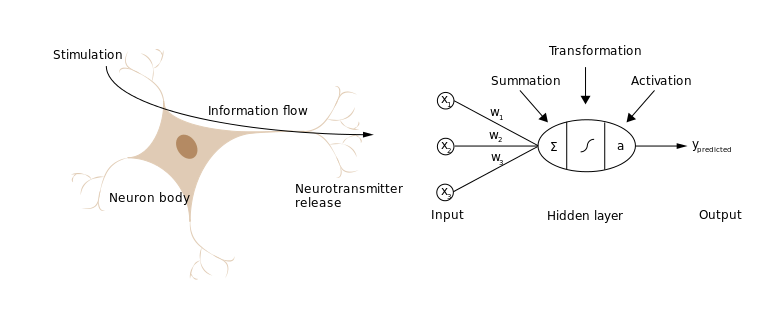

We can describe the intuition of a neural network by looking at how neurons relay and process information to cause a physiological response. Initially, a neuron takes in some stimulation (ie staring at your exam), and channels an electrical signal across the cell to release chemical signals (neurotransmitters) to adjacent neurons. This signal is sent from the initial starting point until it reaches a processing center in the brain, where a decision is made to elicit a specific physiological response (ie increased heart rate, sweaty palms, etc). 

Neural networks are an ensemble machine learning algorithm that takes in an input dataset, transforms the data into complex features, and "learns" parameters that best describe the relationship between the predictor and response variables. To summarize the procedure of a neural network algorithm:

- It takes in an **input** dataset $X$, where each feature is represented as a node ($x_1 ,x_2 ,\textrm{and}\;x_3$ in the diagram above). 

- The data is then processed in the **hidden layer**, where $X$ is transformed into intermediate "features" are not shown in the final model output, denoted as$A$.

- The data undergoes iterative linear and nonlinear transformations and the structure of the data is "learned" by the model until we reach the **output layer**. 

- The final resulting values from each transformation can be classified based on some pre-determined thresholds or kept as continuous values. 

### The components and notation of a neural network

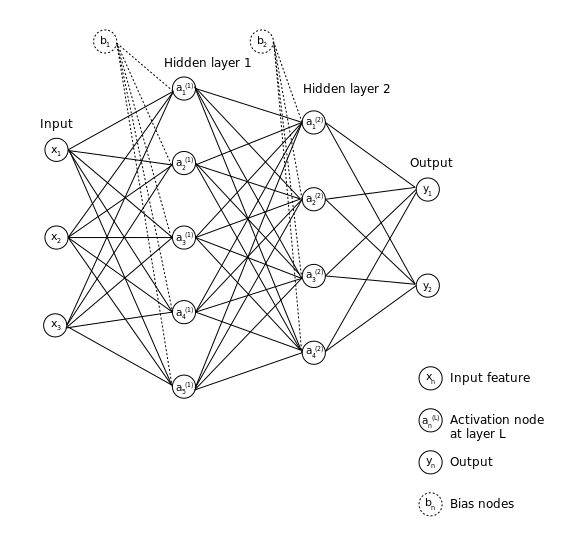

There are several flavors of neural network architectures, each one having their own advantages and disadvantages for solving different problems. The diagram above displays a general **feed-forward neural network**, which is a base model that contains the general principles needed to understand how neural networks work. These principles can then be applied to construct other neural network variations. 

**Each component is described below:**

Input layer: the data ($X_{\textrm{train}}$) we are training the neural network on, where each $n^{\textrm{th}}$ column or feature vector represents a node in the network digram. The diagram above shows 3 features in the input layer.

Hidden layer(s): where the features are transformed into new data representations via linear and non-linear transformations

- Each **activation node** ($a_n$) represents our newly determined complex feature vector. A single hidden layer can consist of several activation nodes that may not necessarily correspond to the number of predictors we are inputting into the model. 

- The **bias nodes** ($b_n$) can be a scalar or vector of values that further influences the model fit. 

Output layer: the final computed values after processing the input data through the hidden layers. 

The diagram above shows a neural network containing two hidden layers - these are considered to be **deep neural networks **if there are multiple hidden layers. To illustrate the basic computations, however, we'll only be dealing with a **shallow neural network** that contains only 1 hidden layer. 

## Neural Network 1: A single activation node

### Forward propagation

To illustrate the process of training a neural network using **forward propagation**, let's consider a simple synthetic dataset with 6 features and one predictor. 

% Initialize inputs using random numbers from default seed
rng('default');
Xtrain = normrnd(0, 1, [50, 6]);
w      = [1; 5; 0; 0; 0; 0];
b      = randn(50, 1);

The network architecture can be visualized in the diagram below.

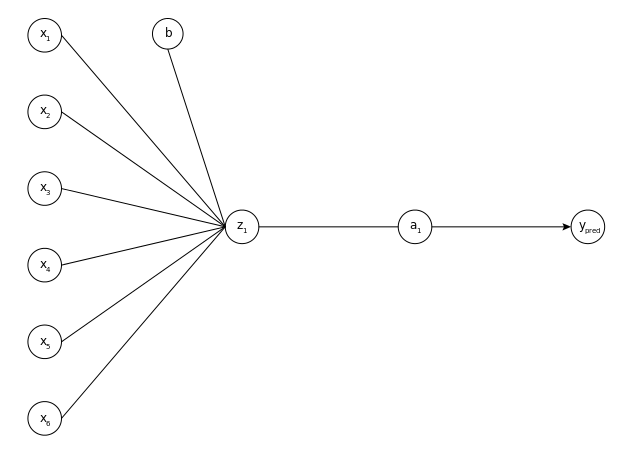

#### Linear transformation

In order for the neural network to learn from the input data, information needs to be fed in the forward direction. This is done through a linear transformation.


$$z=\;X_{\textrm{train}} w+\;b$$


Similar to the regression problems we have encountered previously, we are trying to learn the **weight** parameter $w$ and the intercept $b\ldotp$ When describing neural networks, $b$ is called the **bias**, as it influences the scale of our answers from the neural network.

To train the neural network, we can use the following MATLAB code with synthetic numbers for the weights, training data that is standardized (mean = 0 and variance = 1), and bias. 

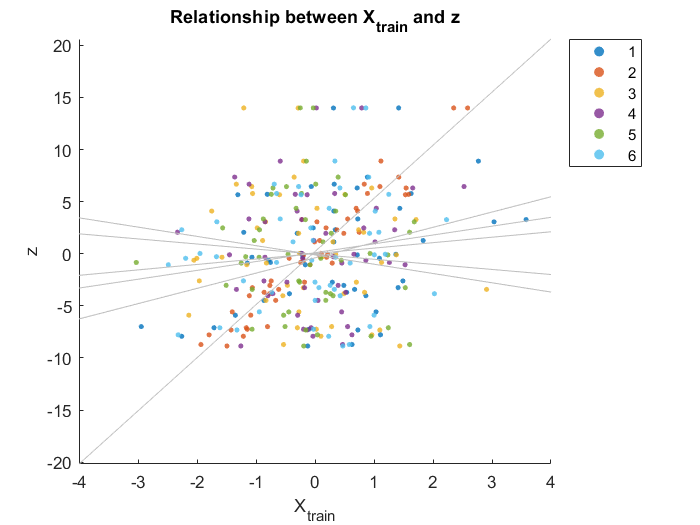

% Compute linear fit z
z = Xtrain * w + b;

% Plot z with respect to input data
figure;
markersize = 10;
featureNames = ['1'; '2'; '3'; '4'; '5'; '6'];

hold on;
for i = 1:size(Xtrain, 2)
    scatter(Xtrain(:, i), z, ...
        markersize, ...
        'filled', ...
        'MarkerFaceAlpha', 0.8);
    %h(i) = lsline;
    %L(:, :, i) = [h(i).XData.', h(i).YData.'];
    %plot(L(:, 1, i), L(:, 2, i));
end
hold off;
lsline;
legend(featureNames, 'location', 'bestoutside');


% Parameters
xlabel('X_{train}');
ylabel('z');
title('Relationship between X_{train} and z');

Looking at the least squares lines in the scatter plot above, some training features are correlated with this linear transformation variable $z$, while other features are anticorrelated.

#### Non-linear transformation using an activation function

The next step of forward propagation process adds non-linearity to the neural network by performing a transformation to $z$ using an **activation function**. One activation function uses the **sigmoid** transformation to bring values closer to either 0 or 1.

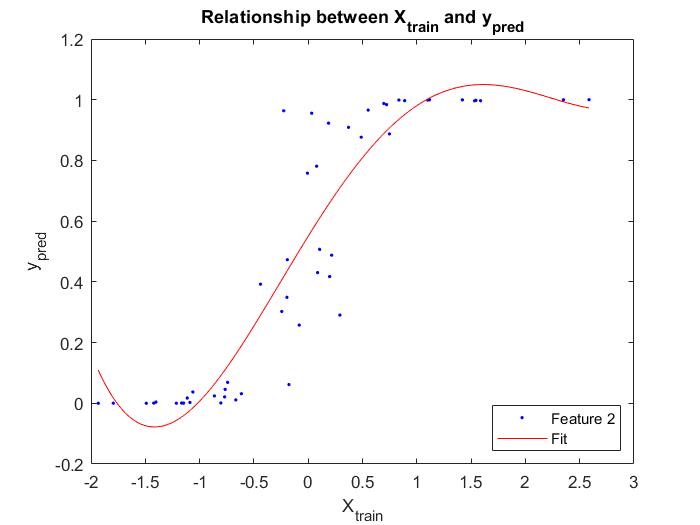

% Transform the new variable z using the sigmoid function
ypred = activationFnc(z, 'Sigmoid');

% Plot a curve for Ypred with respect to input data
figure;
f = fit(Xtrain(:, 2), ypred, 'poly4');
plot(f, Xtrain(:, 2), ypred);
xlabel('X_{train}');
ylabel('y_{pred}');
title('Relationship between X_{train} and y_{pred}');

legend({'Feature 2'; 'Fit'}, 'location', 'southeast');

From the second feature in our synthetic dataset, we are able to discover a decision boundary that best describes the data.

The neural network will have the following components: 

- **Input data:** The Framingham heart disease dataset with 23 features

- **Hidden layer:** 1 layer with N activation nodes

- **Biases:** Assume that the biases are set to 1 ($b_1 =1$)

- **Output:** If a patient receives a stroke

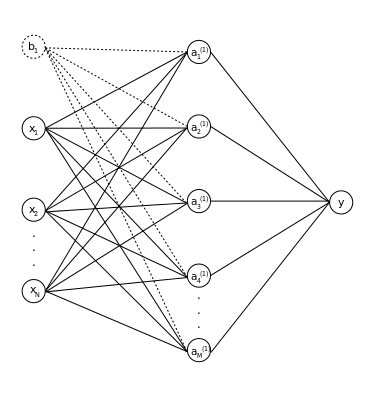

To use the code in the following modules, load the Framingham dataset and process the dataset:

## 2. Overview of Neural Network Implementation

- **Intialize weights** for each connection between nodes in different layers

- **Forward propagation:** Feed the input data $X_{\textrm{train}}$ into the neural network, and for each $L^{\textrm{th}}$ layer, scale the data with weights $W^{\left\lbrack L\right\rbrack }$ and biases $b^{\left\lbrack L\right\rbrack }$, while transforming the scaled data with an activation function $g\left(\cdot \right)$ until we reach the output layer.

- **Use the cost function **to compute the cost $J$, or the error between the predicted output value of the $i^{\textrm{th}}$ iteration and the actual response variable value $y_{\textrm{train}}$.

- **Backpropagation**: Using the cost with respect to weights $W^{\left\lbrack L\right\rbrack }$ and biases $b^{\left\lbrack L\right\rbrack }$, optimize each parameter by moving backward through the network.

- **Repeat** $i$ times until the costs $J$ reach the minimum value or you have reached the number of iterations allotted in the `for` loop. 

### Forward Propagation

**The goal of forward propagation is to compute our predicted values through chained linear and non-linear transformations.**

#### **Intuition for forward propagation**

Let's go back to the analogy of a real neural circuit sending information to the brain from an external stimulus. A neuron only fires neurotransmitters if the stimulus is strong enough to go over a defined threshold that is determined by the physical properties of the cell (ie volume, conductance, etc). Then, and only then, does the electrochemical signal move forward towards the brain. Otherwise, if the signal is weak, this tells the nervous system that the stimulus is not that important, and the signal stops propagating and there will be no physiological response. 

In order for the neural network to learn from the input data, information needs to be fed in the forward direction only. This is the intrinsic nature of the feed-forward network configuration. To pass information in the forward direction, there are two processing steps that occur in each hidden layer or output layer:

- **Preactivation**: there is a weighted sum of inputs. Based on this aggregated sum and the activation function, the node makes a decision whether to pass information forward or not. We will call this weighted sum $Z^{\;\left\lbrack L\right\rbrack }$


$$Z^{\;\left\lbrack L\right\rbrack } =W^{\left\lbrack L\right\rbrack \;T} A^{L-1} +b^L$$


where $L$ denotes the layer we are in. Note that input layer is usually denoted as $L=0$, and thus $A^{\left\lbrack 0\right\rbrack } =X\ldotp$

- **Activation**: the weighted sum $Z$ is passed to an activation function, which adds non-linearity to the network. 


$$A^{\;\left\lbrack L\right\rbrack } =g\left(Z^{\;\left\lbrack L\right\rbrack } \right)$$


where $g\left(\cdot \right)$ is a non-linear function. This process is repeated for $L$ layers until we reach the output layer, where there will be a final processing step. 

What happens when any activation node $a_{\textrm{ij}}^{\left\lbrack L\right\rbrack } =0$? This simply shows how the neural network decides what features are important or not, and thus information will not be transmitted from these "unimportant" features. While this is the goal of the neural network, the activation function itself plays a huge role in determining what is important or not, and is discussed further below.

#### Bias nodes

Note that the bias term is analagous to the intercept in a linear regression model, and serves the same function - to bias the value with a different starting value than 0. This is especially important if we consider the case of sparse datasets, where there are several features in the dataset that contain 0's. 

- If we apply the first step of a linear transformation on those features, we would lose information. Thus, in several cases, the bias value is usually set to 1.

In order for the matrix operations to work correctly, we need to make sure the number of rows for the vector $b$ are the same as the input data ($X$ or $A^{\left\lbrack L\right\rbrack }$). In our example, we are choosing to bias the input by adding $+1$. This can be done in MATLAB:

#### Choosing weights using symmetry breaking

Let's consider two intuitive but bad ways to initializing the weight matrix: setting all weights to 1 or 0. 

- **What happens when we set all of our weights to 0?** Because $Z^{\;\left\lbrack L\right\rbrack } =W^{\left\lbrack L\right\rbrack \;T} A^{L-1} +b^L$, if $W=0$, then we get $Z=b$. Thus, the neural network won't learn from the data, but instead will propagate errors that depend solely on the initial bias term. So don't do this.

- **What happens when we set all of our weights to 1?** $Z^{\;\left\lbrack L\right\rbrack } =A^{L-1} +b^L$, which is essentially a linear function that will be transformed by the activation function $L$ times. Thus, the model won't learn about non-linear relationships that may be occuring within the dataset, making this as useful as linear regression (a useful method most of the time, but not for complex non-linear data).  

A common method to addressing these issues is called **symmetry breaking**, where the weights are initialized to be 1) random, non-zero values and 2) are values that are really small (~ 1E-4). 

Why does this work? The short answer is that we are utilizing randomness to search different initial conditions. When we undergo forward propagation, these small perturbations are carried down the network, and helps the algorithm "learn" from its mistakes in back propagation. More on that later. 

For the matrix operations to work correctly, the size of this matrix must be the following:

- **The number of rows in W:**        the number of columns in the dataset 

- **The number of columns in W:**  the number of activation nodes we're considering in the model. 

A way to initialize the weights for $W^{\left\lbrack 1\right\rbrack }$ and $W^{\left\lbrack 2\right\rbrack }$ in our toy neural network can be done with the following MATLAB code. Note for reproducibility purposes, I've set the random number generator to be the default.

The strategies to choose the number of hidden layers and activation nodes in the neural network are discussed below:

#### Choosing the number of activation nodes and the number of layers in the hidden layer

This is a highly debatable subject with [multiple answers](https://machinelearningmastery.com/how-to-configure-the-number-of-layers-and-nodes-in-a-neural-network/), depending on who you ask, and in what context. The simple answer is that **there is currently no good way to determine the number of hidden layers and activation nodes by a simple equation**. Rather, there are some [common heuristics that are thrown around](https://www.heatonresearch.com/2017/06/01/hidden-layers.html), including the following from Jeff Heaton:

- The number of hidden neurons should be between the size of the input layer and the size of the output layer.

- The number of hidden neurons should be 2/3 the size of the input layer, plus the size of the output layer.

- The number of hidden neurons should be less than twice the size of the input layer.

In short, more is not better, and these hyperparameters should determined empirically by varying different network structures to determine the best performing model for a given dataset. Note that in this context, a **hyperparameter** is a value that is set before the learning process, whereas a **parameter** has values that are derived in the model training process. 

#### Neural Network Activation functions

**Activation functions aim to decide whether a node should be propagate information or not, which will affect the final predicted output.** We will describe two activation functions for neural networks: 

- The sigmoid activation function (which you've already encountered in logistic regression)

- Rectified Linear Units or ReLUs.

**Sigmoid activation function**

We can use the same decision function that we used in logistic regression as the activation function for our value $Z$:


$$Z=W^{\;T} X+b$$



$$g\left(Z\right)=\frac{1}{1+e^{-Z} }$$


When plotted, the function looks like an "S":

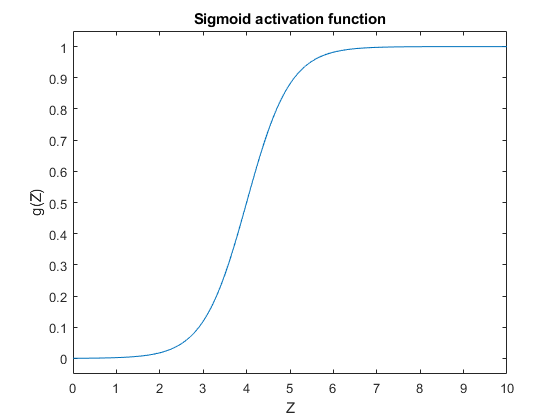

% Example sigmoid activation function
x = 0:0.1:10;
y = sigmf(x,[2 4]);
plot(x,y)
xlabel('Z')
ylabel('g(Z)')
ylim([-0.05 1.05])
title('Sigmoid activation function')

This activation function is particularly useful for classification problems for the following reasons:

- **The function exists between 0 and 1**, making it useful for predicting the probability of an event occuring

- **The function is differentiable**, and we can find the slope of the curve for any two points (this will be especially useful when discussing the backward propagation algorithm).

However, there are several issues with using the sigmoid activation function in specifically deep neural networks, including:

- **Saturation of gradients:** If the activation contains values at the tails of the sigmoid curve (either at 0 or 1), the gradient after each iteration at these nodes approaches 0. At later learning steps (specifically backward propagation), this becomes problematic, as we need these gradients to tell the algorithm whether or not to carry information forward through the neural network. This is very similar to the problem of having our weights set initially to 0 or 1. 

- **The outputs (A) are not zero-centered**: this skews the gradient to extreme values, and makes the optimization part of learning with neural networks harder. 

A more recent and widely used activation are the Rectified Linear Units (ReLUs) and their variations.

**Rectified Linear Units (ReLU)**

The idea of the ReLU is simple: for each positive value of $z$, set it to $\max \left(Z\right)$. If $Z$ is negative, set it to 0


$$g\left(z\right)=\left\lbrace \begin{array}{cc}
\max \left(0,\;Z\right) & \textrm{if}\;Z>0\\
0 & \textrm{if}\;Z<0
\end{array}\right.$$


When plotted, the transformed line will look linear, except for all values that are negative, which are set to 0:

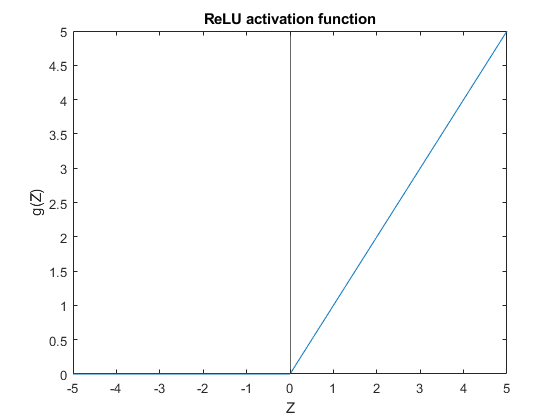

% Example ReLU activation function
n = -5:0.1:5;
a = poslin(n);
plot(n,a)
xline(0);
xlabel('Z')
ylabel('g(Z)')
title('ReLU activation function')

There are [several advantages to the ReLU](https://medium.com/@danqing/a-practical-guide-to-relu-b83ca804f1f7) that make it much more appealing to use than the Sigmoid activation function, primarily that **there is no saturation of gradients in deep neural networks due to the linearity nature of the ReLU when X > 0**. Other advantages include:

- **Cheap computation**: for large neural networks, this is important for training the model.

- **Model sparsity (not to be confused with data sparsity)**: since ReLUs are 0 for all negative inputs, these bad nodes tend to remain inactive in further iterations.

Of course, there are limitations to the ReLU, as there are with any activation function, including:

- **The "**[**dying ReLU**](https://medium.com/@danqing/a-practical-guide-to-relu-b83ca804f1f7)**" problem:** if an activation node keeps on computing negative values (which may be an intrinsic feature of the data itself), it will always output 0. As we iterate the neural network algorithm, this may lead to large parts of the network doing nothing.

There are [several other activation functions or variations of the ReLU](https://medium.com/@himanshuxd/activation-functions-sigmoid-relu-leaky-relu-and-softmax-basics-for-neural-networks-and-deep-8d9c70eed91e) that would allow information for negative values to be considered (such as the leaky ReLU). However, for the remainder of our discussion, we will be using the sigmoid activation function. 

#### **Applying forward propagation to the toy model**

**Step 1: Compute new features from the input layer to hidden layer through linear transformations **

The first step is to linearly transform the input data into a new feature based on two parameters: the weight matrix $W$, and the bias vector $b$. The transformed data will be stored in a temporary variable, usually denoted as $Z^{\left\lbrack n\right\rbrack }$, where $n$ refers to the specific layer in the neural network. The linear equation is described below, and essentially breaks down to the linear regression model at first glance:


$$Z^{\;\left\lbrack 1\right\rbrack } =W^{\left\lbrack 1\right\rbrack \;T} X+b$$


Because we're assuming no biases in our toy model, $b=0$, and the expression simplifies to


$$Z^{\;\left\lbrack 1\right\rbrack } =W^{\left\lbrack 1\right\rbrack \;T} X$$


**Step 2: Perform a non-linear transformation of **$Z$** using the activation function **$g\left(\cdot \right)$

The second step, however, is unique in that we further transform the data using a non-linear activation function $g\left(\cdot \right)$.


$$A^{\;\left\lbrack 1\right\rbrack } =g\left(Z^{\;\left\lbrack 1\right\rbrack } \right)$$


Traditionally, the sigmoid activation function $g\left(Z\right)=\frac{1}{1+e^{-Z} }$ was commonly used as a binary classifier, as is commonly used in logistic regression. However, Rectified Linear Units (ReLUs) are now more commonly used, and are discussed in further sections. 

**Step 3 and 4: Repeat for each layer until we reach the output layer**

The subsequent linear and nonlinear transformations will depend on how many layers are in the neural network. For our model, we can compute the second linear transformation, followed by the last non-linear transformation that will give us our predicted values.


$$Z^{\;\left\lbrack 2\right\rbrack } =W^{\left\lbrack 2\right\rbrack \;T} A^{\;\left\lbrack 1\right\rbrack }$$



$${y_{\textrm{predicted}} \;=A}^{\;\left\lbrack 2\right\rbrack } =g\left(Z^{\;\left\lbrack 2\right\rbrack } \right)$$


#### Forward propagation in MATLAB

The sigmoid activation function used in this example can be called using the `activationFnc.mlx` script, which is written out below:

The steps for forward propagation are outlined below for a single iteration.

Now that we have computed our first predicted values, we need to determine how wrong that model is. That will be determined using the cost.

### Cost function to compute model error

**The goal of computing the cost is to determine how "wrong" our current hypothetical value is from the "true" value.**

Up until this point, we computed the initial values for $y_{\textrm{pred}}$, and now you may be wondering: why are neural networks useful if we're computing random values? 

The answer is because we haven't truly "learned" the final parameters in a general manner. To do that, we need to compute the error from our model to the true value in the training set $y_{\textrm{train}}$, and adjust the tuning parameters in the model, $W$ and $b$. Once the values for $W$ and $b$ converge to stable numbers, the final model has optimal values such that it can output values that look like the truth, or compute predicted values. **The way to compute the error between the model prediction and the true value for our response is the loss function.**

#### **The Cross-Entropy cost function**

For the case where we are using the sigmoid activation function, we can use the **Cross-Entropy (aka Log-Loss) cost function:**


$$J=-\frac{1}{m}\sum_{i=1}^m \left\lbrack -y^{\left(i\right)} \log \left(y_{\textrm{pred}}^{\left(i\right)} \right)-\left(1-y^{\left(i\right)} \right)\log \left(1-y_{\textrm{pred}}^{\left(i\right)} \right)\right\rbrack$$


where

$m$ = number of observations

$y$ = the response variable

$y_{\textrm{pred}}$ = the predicted value for$y$ from forward propagation

The **cost** value can be computed using the code from the `costFunction.mlx` script, which defines the cost function as follows:

Let's now compute the first cost value from the feedforward values with respect to the value we want to learn:

Now that we have a means of evaluating how our model is performing at any given iteration, we need to optimize the model such that it is "learning", and will perform better the next ieration. This is the purpose of the back propagation algorithm, and specifically, we will be using the gradient descent optimization algorithm to find the best parameter values, discussed in the next section. 

### Tuning model parameters using back propagation and gradient descent 

**The goal of back propagation is to "learn" better model parameters that will give us the best estimates for the response variables.**

Now that we've computed the costs, we can use them to tell the model how to adjust the tuning parameters $W$ and $b$. This process is called **back propagation, **and the optimization algorithm we will use to get the best values of $W$ and $b$ is called** gradient descent.**

#### **The intuition for gradient descent**

The concept for gradient descent optimization process can be described with the following problem: 

Suppose you're on the top of a tall hill, and you are blindfolded. You want to get to the lowest part of the valley, which is displayed on the surface plot below.

% Gradient surface
[M, N, O] = peaks(25);
surf(M, N, O);
zlabel('Altitude');
xlabel('Latitude');
ylabel('Longitude');

If you go in any random direction from the top, you'll hit a low point, but depending on the direction and speed in which you go down the hill, you may hit the point that is the lowest part of our surface, which is the **global minimum**. 

Looking at the surface plot, where the `x-axis` is your predictor value, the `y-axis` is the response value, and the `z-axis` is the cost computed, we can appreciate the learning problem for our algorithm, where we are trying to minimize the model error. This the problem gradient descent tries to solve: it is an optimization algorithm that looks at the error from your model, adjusts the model parameters, and re-evaluates the error. If the error is smaller than what it was before, it keeps those parameter values until they stop changing until we reach a minimum error value. 

There are challenges to using gradient descent. Going back to the surface analogy, imagine that you have reached a low point that is not the global minimum. It is possible to be trapped in the **local minima - **because you feel that the surface around you starts to incline, you believe that you are at the lowest point and stop prematurely. 

Now that we have a visual representation for the problem, let's see the math behind the gradient descent algorithm

#### **Gradient descent**

The two equations we're interested in to implement gradient descent are the update rules for $W$ and $b$:


$$\begin{array}{l}
{\mathrm{W}}^{\left\lbrack \mathrm{n}\right\rbrack } ={\mathrm{W}}^{\left\lbrack \mathrm{n}\right\rbrack } -\left(\alpha \cdot d{\mathrm{W}}^{\left\lbrack \mathrm{n}\right\rbrack } \right)\\
{\mathrm{b}}^{\left\lbrack \mathrm{n}\right\rbrack } \;\;={\;\;\mathrm{b}}^{\left\lbrack \mathrm{n}\right\rbrack } -\left(\alpha \cdot d{\mathrm{b}}^{\left\lbrack \mathrm{n}\right\rbrack } \right)
\end{array}$$
 

such that we are minimizing the cost, and we are approaching the cost minimum with respect to $W$ and $b$ and $\alpha$ is the **learning rate** hyperparameter. This opimization problem can be visualized using the following plot:

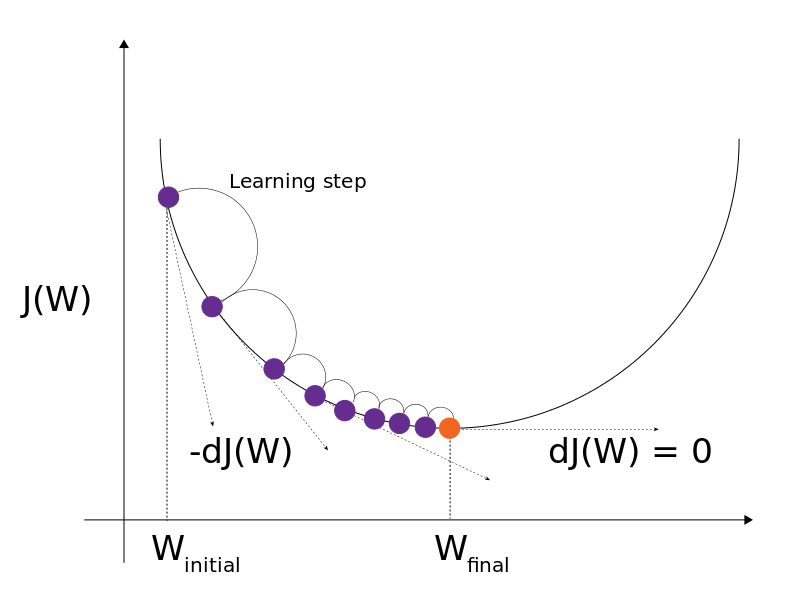

From our initial random initialization of a given weight, we most likely were pretty wrong about the value to use, resulting in a high cost $J\left(W\right)$. By taking a step in either the positive or negative direction, we are computing the gradient $\textrm{dJ}\left(W\right)$. By adjusting the value of $W$by subtracting the gradient, we improve our answer and lower the cost. By iterating this procedure, we get closer to our best value of $W$ when $\textrm{dJ}\left(W\right)=0$. 

#### The learning rate

The learning rate $\alpha$ affects the rate in which we descend down the gradient. Let's now explore what happens when we change $\alpha$:

- With a high $\alpha$, we descend the gradient faster but also risk overshooting the lowest point of the cost function. 

- Conversely, with a low $\alpha$, we do move in the direction of gradient, but we need to recompute a new answer frequently, making our computation time-consuming. 

Thus, we need to choose our $\alpha$ carefully so that it balances these two points. 

#### Further intuition on the gradients in gradient descent

To further gain some intuition for the gradient equations, let's consider three scenarios, where the derivative rate for the weights $\textrm{dW}$ is positive, negative, or zero during our update: 

- The derivative rate is positive: If the derivative rate is positive, it means that an increase in the value of the weight will increase the error. Thus, the new weight value should be smaller.

- The derivative rate is negative: If the derivative rate is negative, it means that an increase in weight will decrease the error. Thus, the new weight values should be larger.

- The derivative rate is zero: If the derivative is 0, it means that we are at a stable minimum. Thus, no updates are needed, and we have reached a stable state.

The same intuition can be applied for updating the bias vector. Now that we have gone over the gradient equations for $W$ and $b$, let's put it in context of the back propagation algorithm.

#### Intuition for back propagation

Now that we have a method for determining which direction we should tune our parameters $W$ and $b$, we can back-calculate better values with a given cost using back propagation.** Specifically, we need to find the node that is responsible for most of the loss in every layer, so that we can penalize it by giving it a smaller weight value, and lessening the total loss of the model. **

To do that, we need to compute the gradients for $W$ and $b$. Because we know the cost with respect to our predicted output, and we know the relationship between the predicted values and the activation functions, we can use the chain rule to compute the change cost with respect to the change in weight or bias:

$\frac{\vartheta J}{\vartheta W}$ = $\frac{\vartheta J}{\vartheta y_{\textrm{pred}} }\cdot \frac{\vartheta y_{\textrm{pred}} }{\vartheta Z}\cdot \frac{\vartheta Z}{\vartheta W}$ 

$\frac{\vartheta J}{\vartheta b}$ = $\frac{\vartheta J}{\vartheta y_{\textrm{pred}} }\cdot \frac{\vartheta y_{\textrm{pred}} }{\vartheta Z}\cdot \frac{\vartheta Z}{\vartheta b}$ 

Depending on the neural network activation function, $\frac{\vartheta Z}{\vartheta W}$ will vary. We won't go over the derivation of the terms, but if you're interested in the derivation, someone already wrote about this [here](https://medium.com/@pdquant/all-the-backpropagation-derivatives-d5275f727f60). Once we complete the derivation for the sigmoid activation function, the most relevant equations to update the parameters are the following: 


$$\begin{array}{l}
{\textrm{dZ}}^{\left\lbrack L\right\rbrack } =A^{\left\lbrack L\right\rbrack } -Y\\
d{\mathrm{W}}^{\left\lbrack L\right\rbrack } =\frac{1}{m}\sum_{i=1}^n \left({\textrm{dZ}}^{\left\lbrack L\right\rbrack } \cdot A^{\left\lbrack L\right\rbrack \;T} \right)\\
{\textrm{db}}^{\left\lbrack L\right\rbrack } =\frac{1}{m}\sum_{i=1}^n \left({\textrm{dZ}}^{\left\lbrack \mathrm{n}\right\rbrack } \right)\\
{\textrm{dZ}}^{\left\lbrack L-1\right\rbrack } =W^{\left\lbrack L\right\rbrack T} {\textrm{dZ}}^{\left\lbrack L\right\rbrack } {g^{\prime } }^{\left\lbrack L\right\rbrack } \left(Z^{L-1} \right)\\
\vdots \\
{\textrm{dZ}}^{\left\lbrack 1\right\rbrack } =W^{\left\lbrack 2\right\rbrack T} {\textrm{dZ}}^{\left\lbrack 2\right\rbrack } {g^{\prime } }^{\left\lbrack 1\right\rbrack } \left(Z^1 \right)\\
d{\mathrm{W}}^{\left\lbrack 1\right\rbrack } =\frac{1}{m}\sum_{i=1}^n \left({\textrm{dZ}}^{\left\lbrack 1\right\rbrack } \cdot A^{\left\lbrack 1\right\rbrack \;T} \right)\\
{\textrm{db}}^{\left\lbrack 1\right\rbrack } =\frac{1}{m}\sum_{i=1}^n \left({\textrm{dZ}}^{\left\lbrack 1\right\rbrack } \right)
\end{array}$$


where $L$ is the layer and $\alpha$ is the **learning rate** hyperparameter. 

#### Applying back propagation to the toy model

Specifically referring back to our toy model, let's get the expressions for back-calculating better $W$ and $b$ values:


$$\begin{array}{l}
{\textrm{dZ}}^{\left\lbrack 2\right\rbrack } =y_{\textrm{predicted}} -y\\
d{\mathrm{W}}^{\left\lbrack 2\right\rbrack } =\frac{1}{m}\sum_{i=1}^n \left({\textrm{dZ}}^{\left\lbrack 2\right\rbrack } \cdot y_{\textrm{predicted}}^T \right)\\
{\textrm{dZ}}^{\left\lbrack 1\right\rbrack } =W^{\left\lbrack 2\right\rbrack T} {\textrm{dZ}}^{\left\lbrack 2\right\rbrack } {g^{\prime } }^{\left\lbrack 1\right\rbrack } \left(Z^{\left\lbrack 1\right\rbrack } \right)\\
d{\mathrm{W}}^{\left\lbrack 1\right\rbrack } =\frac{1}{m}\sum_{i=1}^n \left({\textrm{dZ}}^{\left\lbrack 1\right\rbrack } \cdot A^{\left\lbrack 1\right\rbrack \;T} \right)\\
db^{\left\lbrack 1\right\rbrack } =\frac{1}{m}\sum_{i=1}^n {\textrm{dZ}}^{\left\lbrack 1\right\rbrack } \;
\end{array}$$


And that's it! Once we have completed this round of gradient descent, we would essentially iterate the forward and backward propagation algorithms until the values converge to our final answer

#### Backward propagation in MATLAB

The way to code this up would be the following:

## 3. Putting it all together

We have gone over how to train a neural network from scratch, which can be summarized below:

- **Intialize weights** for each connection between nodes in different layers

- **Forward propagation:** Feed the input data $X_{\textrm{train}}$ into the neural network, and for each $L^{\textrm{th}}$ layer, scale the data with weights $W^{\left\lbrack L\right\rbrack }$ and biases $b^{\left\lbrack L\right\rbrack }$, while transforming the scaled data with an activation function $g\left(\cdot \right)$ until we reach the output layer.

- **Use the cost function **to compute the cost $J$, or the error between the predicted output value of the $i^{\textrm{th}}$ iteration and the actual response variable value $y_{\textrm{train}}$.

- **Backpropagation using gradient descent**: Using the cost with respect to weights $W^{\left\lbrack L\right\rbrack }$ and biases $b^{\left\lbrack L\right\rbrack }$, optimize each parameter by moving backward through the network.

- **Repeat** $i$ times until the costs $J$ reach the minimum value or you have reached the number of iterations allotted in the `for` loop. 

Now let's put what we have learned into practice by coding up the neural network.

### MATLAB Implementation of a shallow neural network

% 1. Read in the datasetand and remove rows that contain NaN
data = readtable('frmgham.xls');
data = rmmissing(data);

X = data(:, 2:24);
Y = data(:, 31);
m = size(X, 2);

trainingSize = 0.8;
randomState  = false;
[Xtrain, Ytrain, Xtest, Ytest] = trainTestSplit(X, Y, trainingSize, randomState);

% 2. Intialize some variables for the shallow neural network
rng('Default');

numberOfActivationNodes = 12;
W1                      = rand([size(Xtrain, 1), numberOfActivationNodes]) * 0.1;
W2                      = rand([size(Xtrain, 1), numberOfActivationNodes]) * 0.1;
b1                      = 1;
alpha                   = 0.05;
num_iters               = 2;         

for i = 1:num_iters
    
    % First, run forward propagation to get values for ypred
    Xtrain     = Xtrain + b1;
    Z1         = W1' * Xtrain;
    A1         = activationFnc(Z1, 'Sigmoid');
    Z2         = W2 * A1;
    A2         = activationFnc(Z2, 'Sigmoid');
    [ypred, p] = max(A2, [], 2);
    
    % Second, compute the cost value using the cost function 
    J(i) = costFunction(Ytrain, ypred);
    
    % Back propagation from output layer back to hidden layer
    dZ2  = A2 - Ytrain;
    dW2  = (1/m) .* sum(dZ2 * A2');
    
    % Back propagation from hidden layer to the input layer
    dgZ1 = Z1    .* (1 - Z1);
    dZ1  = dZ2   .* (W2 * dgZ1);
    dW1  = (1/m) .* sum(dZ1 * A1');
    db   = (1/m) .* sum(dZ1);
    
    % Updated value from back propagation
    W2 = W2 - (alpha .* dW2)';
    W1 = W1 - (alpha .* dW1);
    b1 = b1 - (alpha .* db);
    
end

## Review questions

- What are the three general sections of a feed-forward neural network, and what does each section do?

- Do we need to perform data normalization for training and testing a neural network? Why or why not?

- What is the role of an activation function in a neural network? Give an example of one, and how it comes to a decision.

- What is the objective of the cost function, and how do we achieve this objective?

- What happens if the learning rate is set too low? Too high?

- What is the purpose of back propagation? 

- What is overfitting and underfitting? How can you combat these two problems?

- How are weights initialized in a neural network? What happens to your answers when you initialize all weights equal to 0?

## Useful reading and references

- A [generalized tutorial for learning about neural networks](https://medium.com/datathings/neural-networks-and-backpropagation-explained-in-a-simple-way-f540a3611f5e) that is language-agnostic.

- The [various flavors of neural networks](https://towardsdatascience.com/the-mostly-complete-chart-of-neural-networks-explained-3fb6f2367464), and how they are currently being used in real-world settings.

- Heuristics on deciding [how many hidden layers and activation nodes](https://machinelearningmastery.com/how-to-configure-the-number-of-layers-and-nodes-in-a-neural-network/) to initialize in a neural network.

- [Other activation functions, their usage, and generalizations about pros/cons](https://medium.com/@himanshuxd/activation-functions-sigmoid-relu-leaky-relu-and-softmax-basics-for-neural-networks-and-deep-8d9c70eed91e).

- [Andrew Ng's CS229 deep learning notes ](http://cs229.stanford.edu/notes/cs229-notes-deep_learning.pdf)for a more in-depth understanding of the mathematics and algorithms for constructing neural networks from scratch.

- The [deep learning specialization on Coursera](https://www.coursera.org/specializations/deep-learning) (also taught by Andrew Ng and others at [deeplearning.ai](https://www.deeplearning.ai/)). It consists of 5 courses, all on deep learning and optimizing these models. The course is taught in Python with the specific usage of the `numpy` and `scipy` libraries.

- [Deep Learning](http://www.deeplearningbook.org/) by Ian Goodfellow and Yoshua Bengio - two pioneers in modern deep learning. The book covers 1-2 semester's worth of material for not the basics of constructing and applying deep neural networks, but more cutting-edge techniques in Artificial Intelligence.